# Simulink Profiler

Copyright 2023-2024 The MathWorks, Inc.

The Simulink profiles can point to sources of simulation slowdowns. It captures model and block execution timings while the model simulates and with that can identify model parts that are computationally most expensive. It is:

- Most useful for fixed-step simulations

- Useful to identify which components of the model take longer to execute. 

Open a model:

openExample('simulink_automotive/ModelingAFaultTolerantFuelControlSystemExample') 

Open the Simulink Profiler:

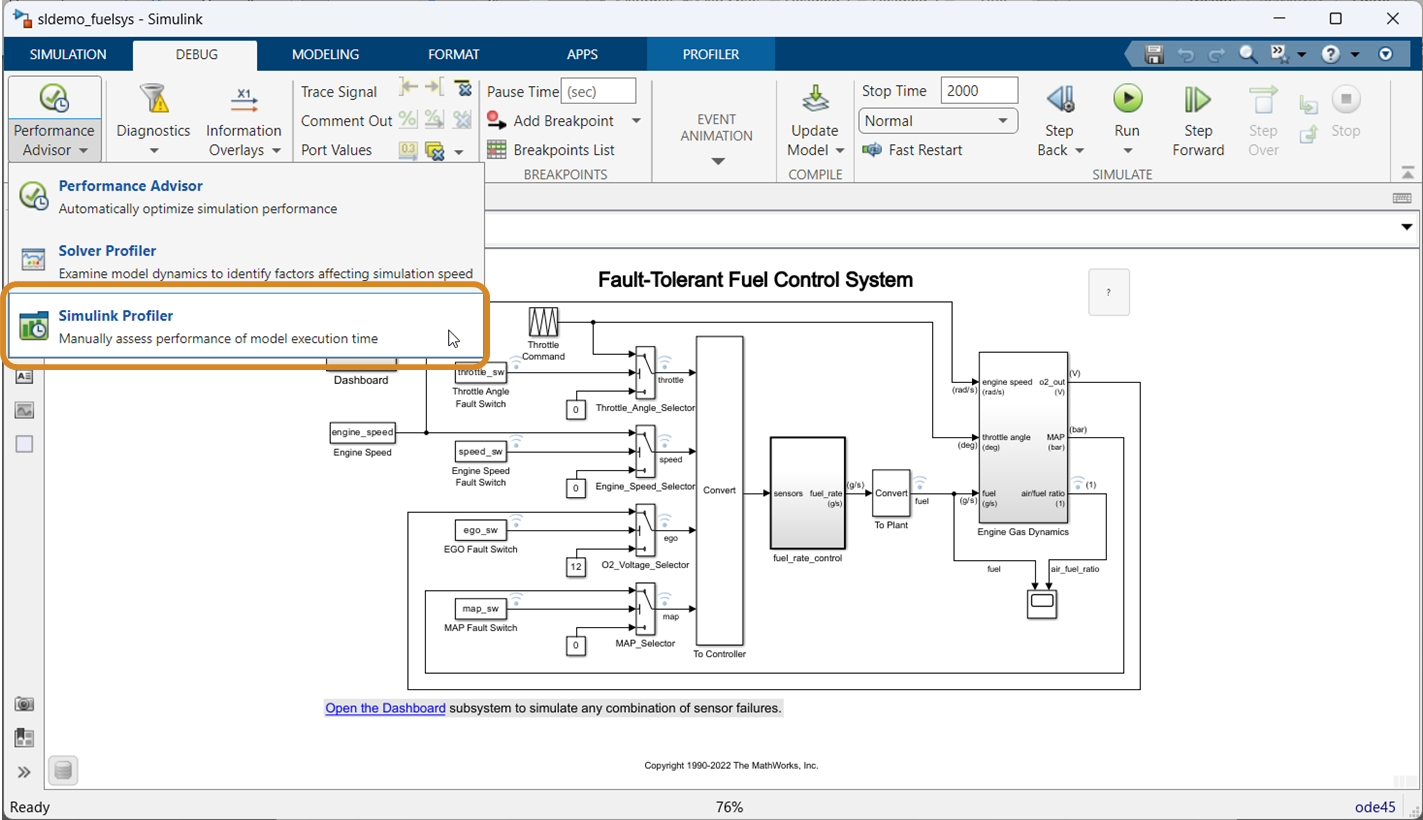

Start profiling the model:

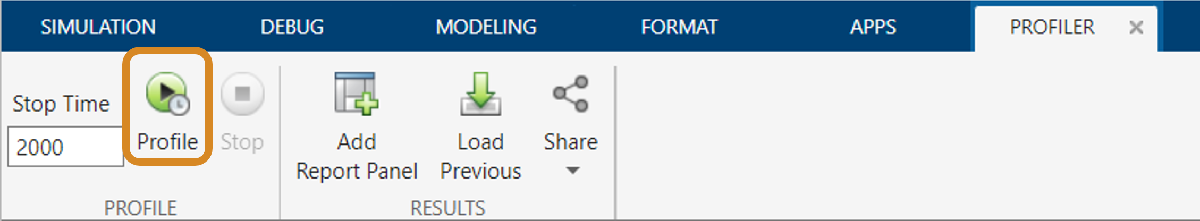

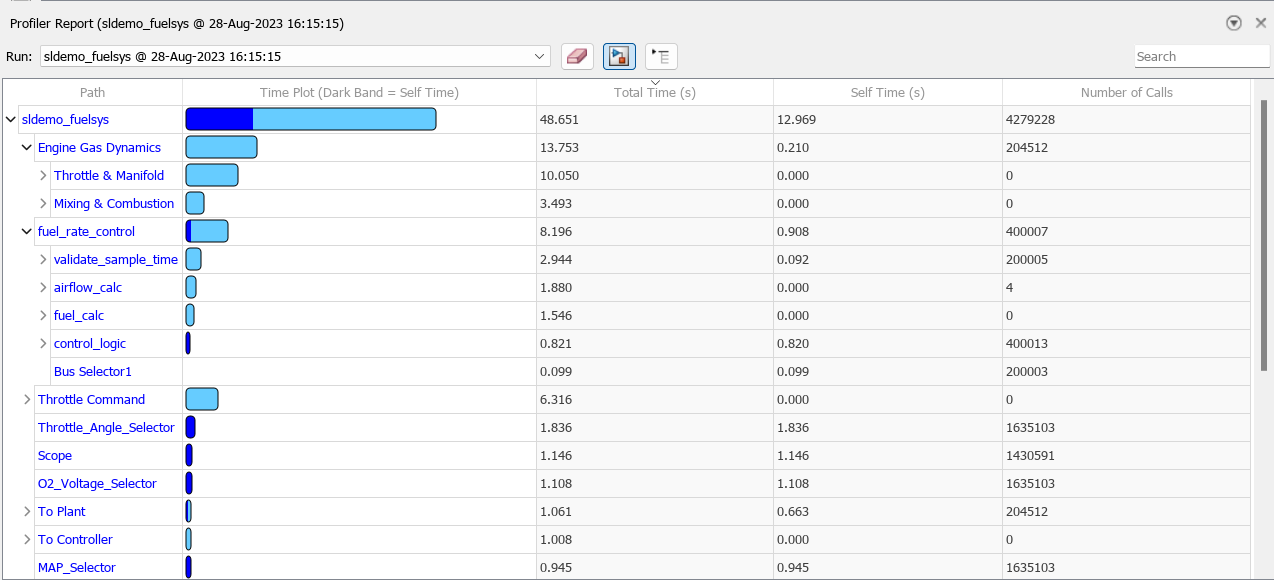

- Report shows results on subsystem an block level

- The results consists of number of individual calls to the component as well as it's total execution time and it's self time 

- The self time refers to the total duration of execution that specific block 

- Total time refers to the execution time for a component with all it's subcomponents 

Use the Property Inspector to view more details:

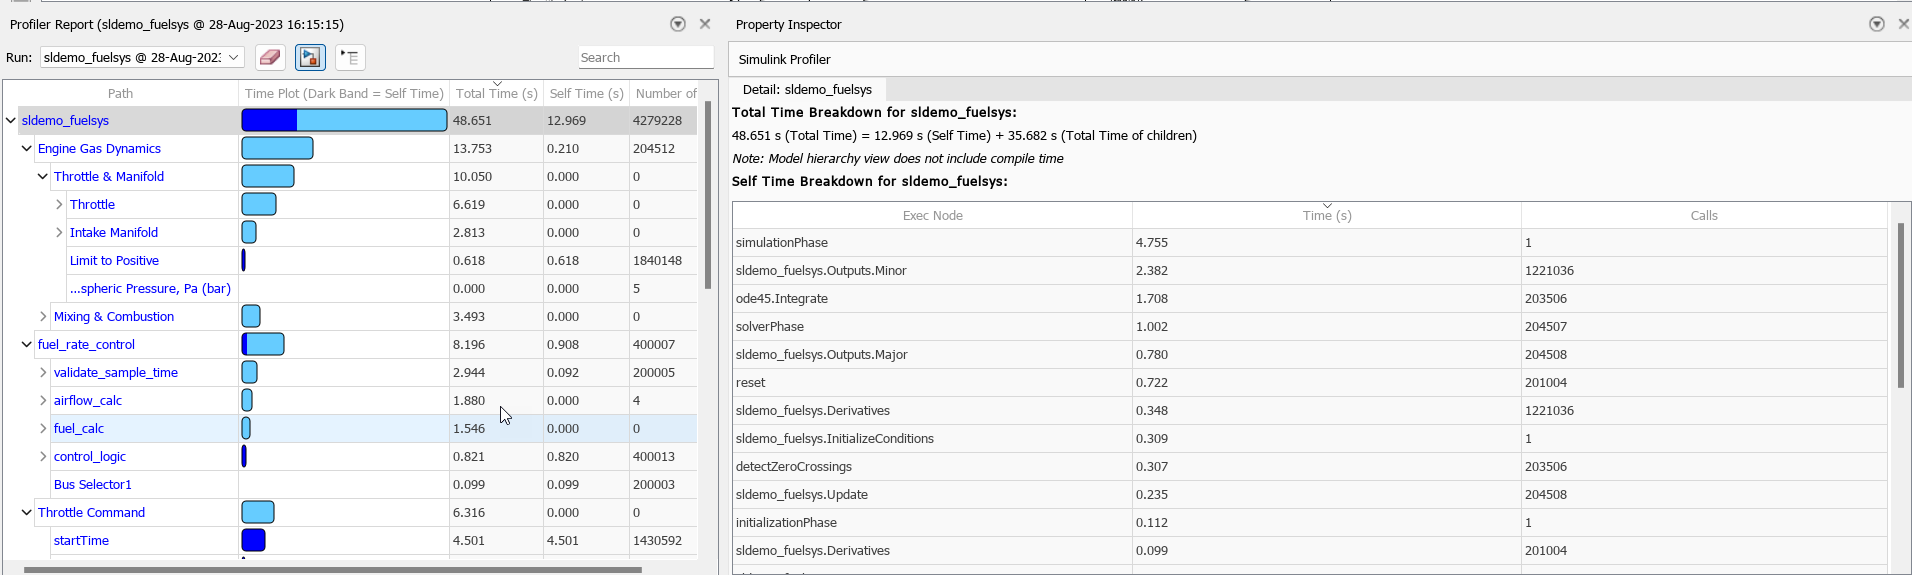

This report is helpful to identify which are the most computationally expensive parts of the model. 

**Note:**

- If you are using a variable-step solver and your most signifact bottleeck is that the solver is taking too many steps or is stalling, consider to use the Solver Profiler to identify the underlying issues

- if parts of your model are a Simscape network this will be cumulated as one item. To investigate the Simscape portion of the model in more depth, the Solver Profiler is also better suited.